alpha = 1 + mod(276, 3);

# Problem 1

## Q.1)

fs = 120; % Sampling rate (samples per second)
duration = 2; % Duration of the signal (seconds)
frequency = 15 * alpha; % Frequency in Hertz
N = fs * duration; % Total number of samples

% Generate the unit amplitude sinusoidal signal
t = (0 : N-1) / fs;
x = cos(2 * pi * frequency * t);

% Compute the DFT of the first 120 samples
X = fft(x(1 : 120));

% Create a frequency axis
frequencies = linspace(0, fs/2, 61); % 61 frequency points

% Plot magnitude of the DFT against frequency
plot(frequencies, abs(X(1:61)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('DFT Magnitude vs. Frequency');
grid on;


## Q.2)

% Compute the DFT of the first 130 samples
X_130 = fft(x(1:130));

% Plot magnitude of the DFT against frequency
hold on; % Hold the current plot
plot(frequencies, abs(X_130(1:61)), 'g--'); % Green dashed line for 130 samples
legend('120 Samples', '130 Samples');


# Problem 2

alpha_values = [1, 2, 3];
A_values = [120, 140, 160];
B_values = [126, 146, 166];
fs = 200;  % sampling rate (samples per second)
T = 10;    % signal duration (seconds)

% sample lengths to analyze (as integers)
sample_lengths = [215, 415, 1115, 1515, 1915];


% Loop over parameter combinations
for i = 1:numel(alpha_values)
    alpha = alpha_values(i);
    A = A_values(i);
    B = B_values(i);

    % Generate the signal xa(t)
    t = linspace(0, T, fs*T);  % Time vector
    xa_t = 0.1 * sin(A*pi*t) + cos(B*pi*t);

    % Perform DFT analysis for different sample lengths
    for j = 1:numel(sample_lengths)

        % frequency axis
        frequencies = (0:sample_lengths(j)-1) * fs/sample_lengths(j);

        N = sample_lengths(j);

        % Extract the first N samples
        xa_samples = xa_t(1:N);

        % Compute the DFT
        dft_result = fft(xa_samples);

        % Calculate the magnitude of the DFT
        dft_magnitude = abs(dft_result);

        % Plot the DFT magnitude
        figure;
        plot(frequencies, dft_magnitude);
        xlabel('Frequency (Hz)');
        ylabel('Magnitude');
        title(['DFT Magnitude for Sample Length = ' num2str(N)]);
    end
end


# Problem-3

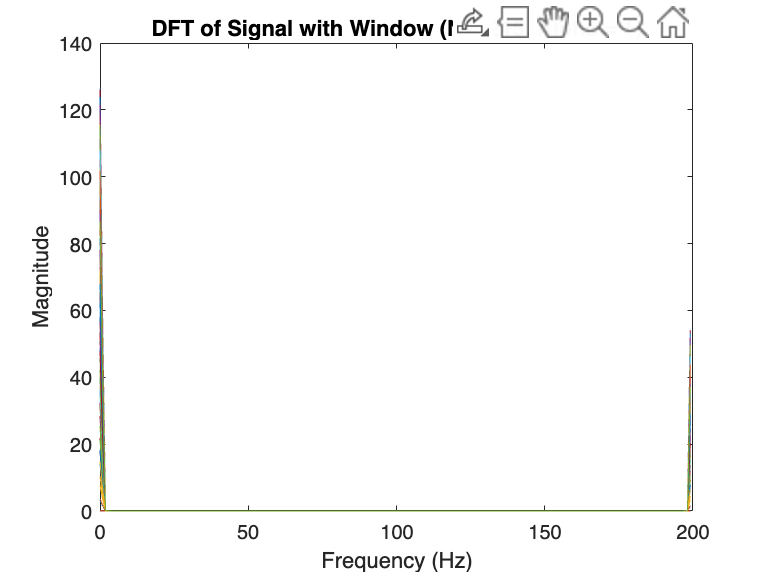

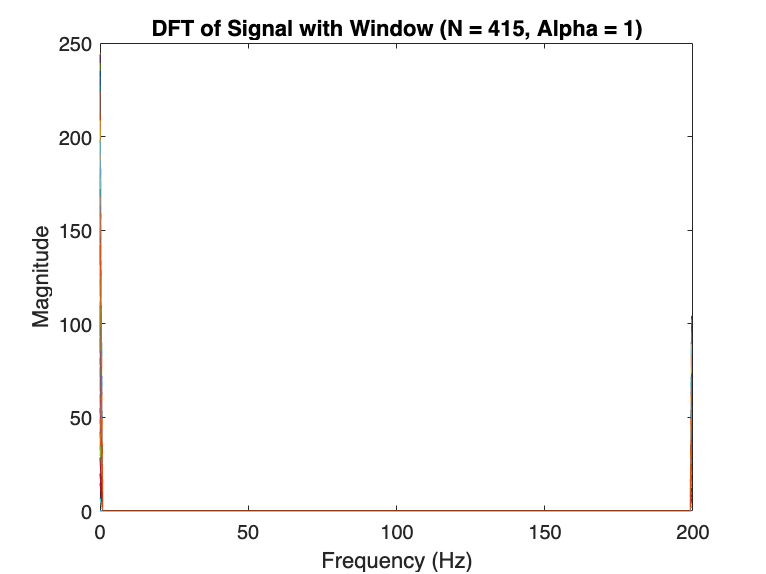

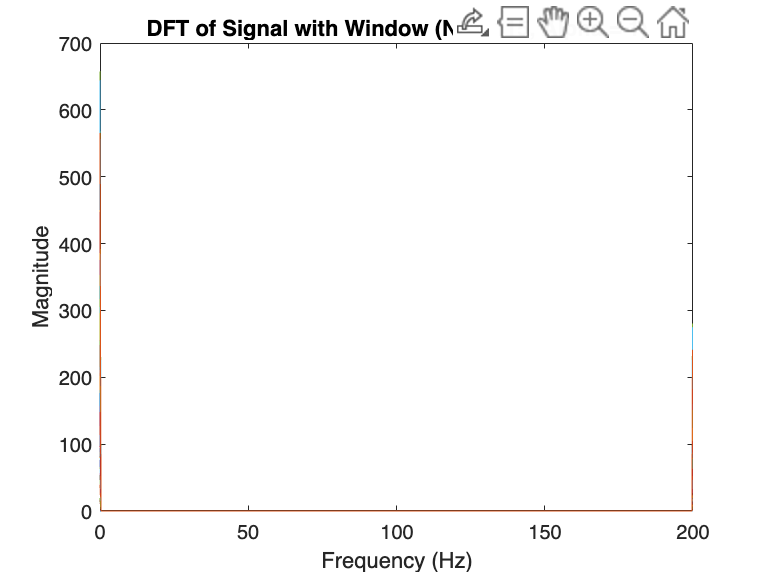

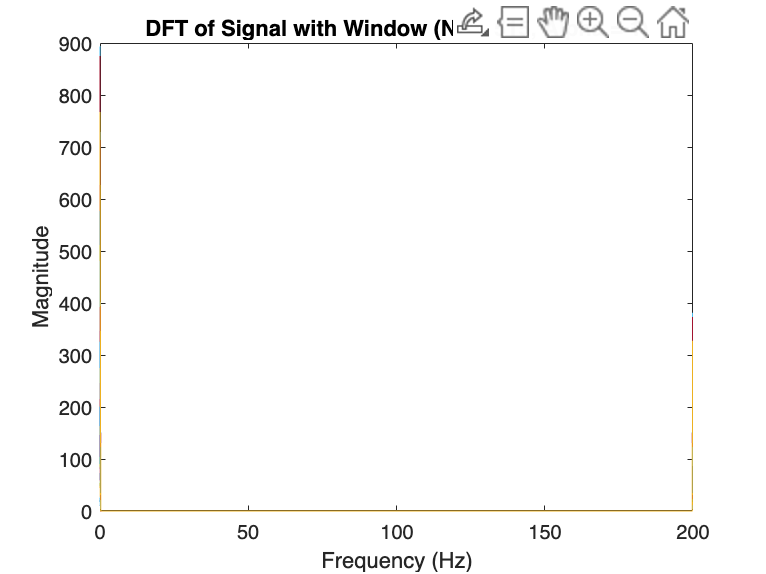

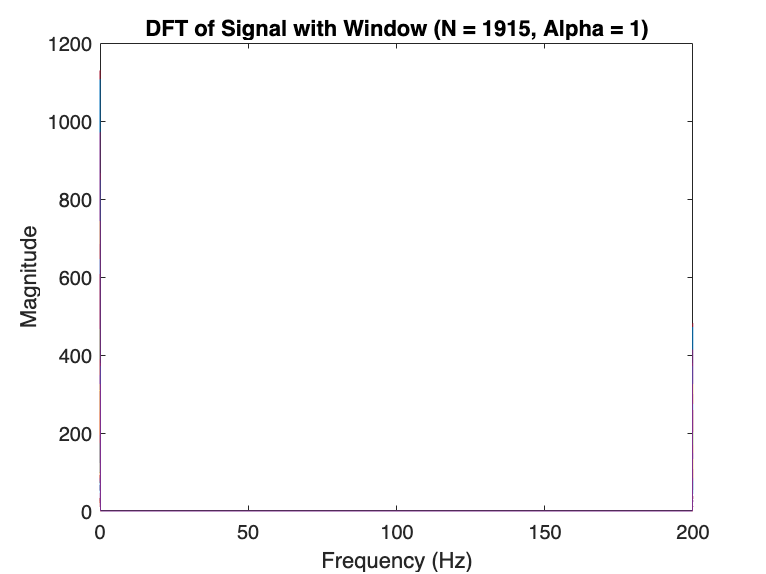

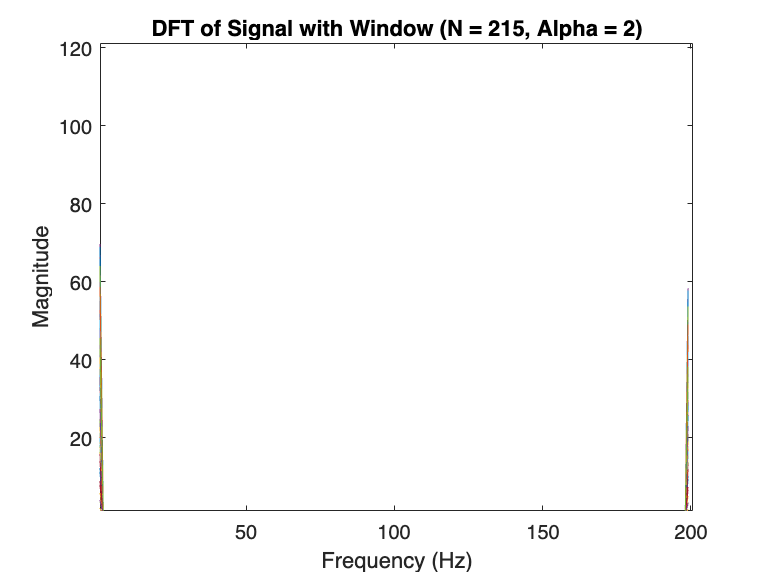

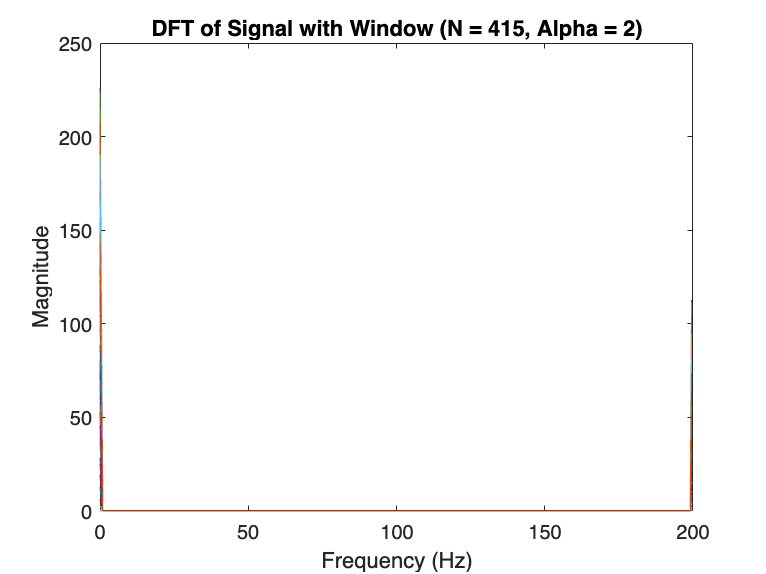

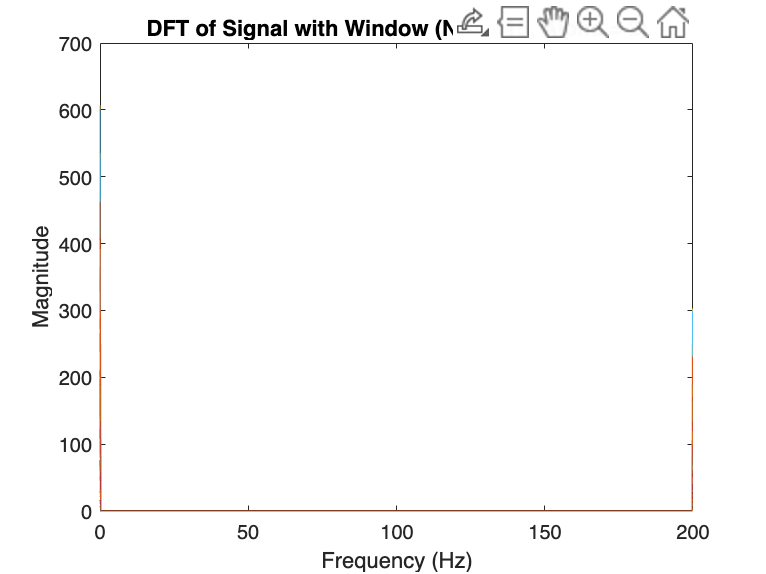

alpha_values = [1, 2, 3];
A_values = [120, 140, 160];
B_values = [126, 146, 166];
duration = 10; % Duration 
sampling_rate = 200; % Samples per second

% time vector
t = 0:1/sampling_rate:duration-1/sampling_rate;

for i = 1:numel(alpha_values)
    alpha = alpha_values(i);
    A = A_values(i);
    B = B_values(i);

    % Generating signal
    xa =  0.1*sin(A * pi * t) + cos(B * pi * t);

    % different numbers of samples to plot DFT
    sample_counts = [215, 415, 1115, 1515, 1915];

    for j = 1:numel(sample_counts)
        N = sample_counts(j);

        % window depending on alpha
        if alpha == 1 
            window = hamming(N);
        elseif alpha == 2
            window = hanning(N);  
        elseif alpha == 3
            window = blackman(N);
        end

        % window to the signal
        xa_windowed = xa(1:N) .* window;

        % DFT of the windowed signal
        dft = fft(xa_windowed);
        frequencies = (0:N-1) * sampling_rate / N;
        magnitude = abs(dft);

        % Plot the DFT for each N in a separate figure
        figure;
        plot(frequencies, magnitude);
        title(['DFT of Signal with Window (N = ', num2str(N), ', Alpha = ', num2str(alpha), ')']);
        xlabel('Frequency (Hz)');
        ylabel('Magnitude');
    end
end

# Problem-4

% Load data from Exp4Dataα.txt
data = load('Exp4Data1.txt');

% sampling rate and signal length
Fs = 1000;
signal_length = length(data);

% Hamming window
hamming_window = hamming(signal_length);
data_hamming = data .* hamming_window;

% rectangular window (no window)
data_rectangular = data;

% Discrete Fourier Transform (DFT) with zero-padding
n_fft = 10000; % Number of points for zero-padding
fft_result_hamming = fft(data_hamming, n_fft) / n_fft;
fft_result_rectangular = fft(data_rectangular, n_fft) / n_fft;

% frequency axis in Hz
frequencies = (0:n_fft-1) * (Fs / n_fft);

% Plot the magnitude spectrum for both Hamming and rectangular windows
figure;
subplot(2, 1, 1);
plot(frequencies, abs(fft_result_hamming));
title('Magnitude Spectrum with Hamming Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2, 1, 2);
plot(frequencies, abs(fft_result_rectangular));
title('Magnitude Spectrum with Rectangular Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% frequencies (in Hz)
[~, index1] = max(abs(fft_result_hamming));
frequency1 = frequencies(index1);
fprintf('Frequency 1 using Hamming Window: %.3f Hz\n', frequency1);

[~, index2] = max(abs(fft_result_rectangular));
frequency2 = frequencies(index2);
fprintf('Frequency 1 using Rectangular Window: %.3f Hz\n', frequency2);
